**Wstęp**

Podczas tych zajęć laboratoryjnych miałem za zadanie aproksymować układ o transmitancji wysokiego rzędu transmitancją niższego rzędu. Dzięki temu łatwiej można było obserwować zmiany układu oraz poddawać go analizie. Winny byłem wykonać trzy zadania. Do wszystkich wykorzystałem simulinka i jego rozległe peryferia. Kluczowe było dojście do ostatniego podpunku gdzie w sposób numeryczny program wraz z jego sercem czyli napisaną przeze mnie funkcją dobrał współczynniki tak aby błąd czyli różnica pomiędzy odpowiedziami obu układów była możliwie jak najmniejsza.

**Zadanie 1**

Pierwsze zadanie polegało na zbudowaniu układu porównawczego dla aproksymacji Pade'go pierwszego i drugiego rzędu.Brałem tu pod analizę układ inercyjny I rzędu. Chodziło przede wszystkim o odejście od formy eksponencjalnej ze współczynnikiem theta w potędze eksponenty. Dzięki użyciu formy wielomianowej łatwiej będzie analizować system. Dalej ważne było zauważenie, że aproksymacja wyższym rzędem będzie poczyniała dokładniejsze wyniki do formy eksponencjalnej.

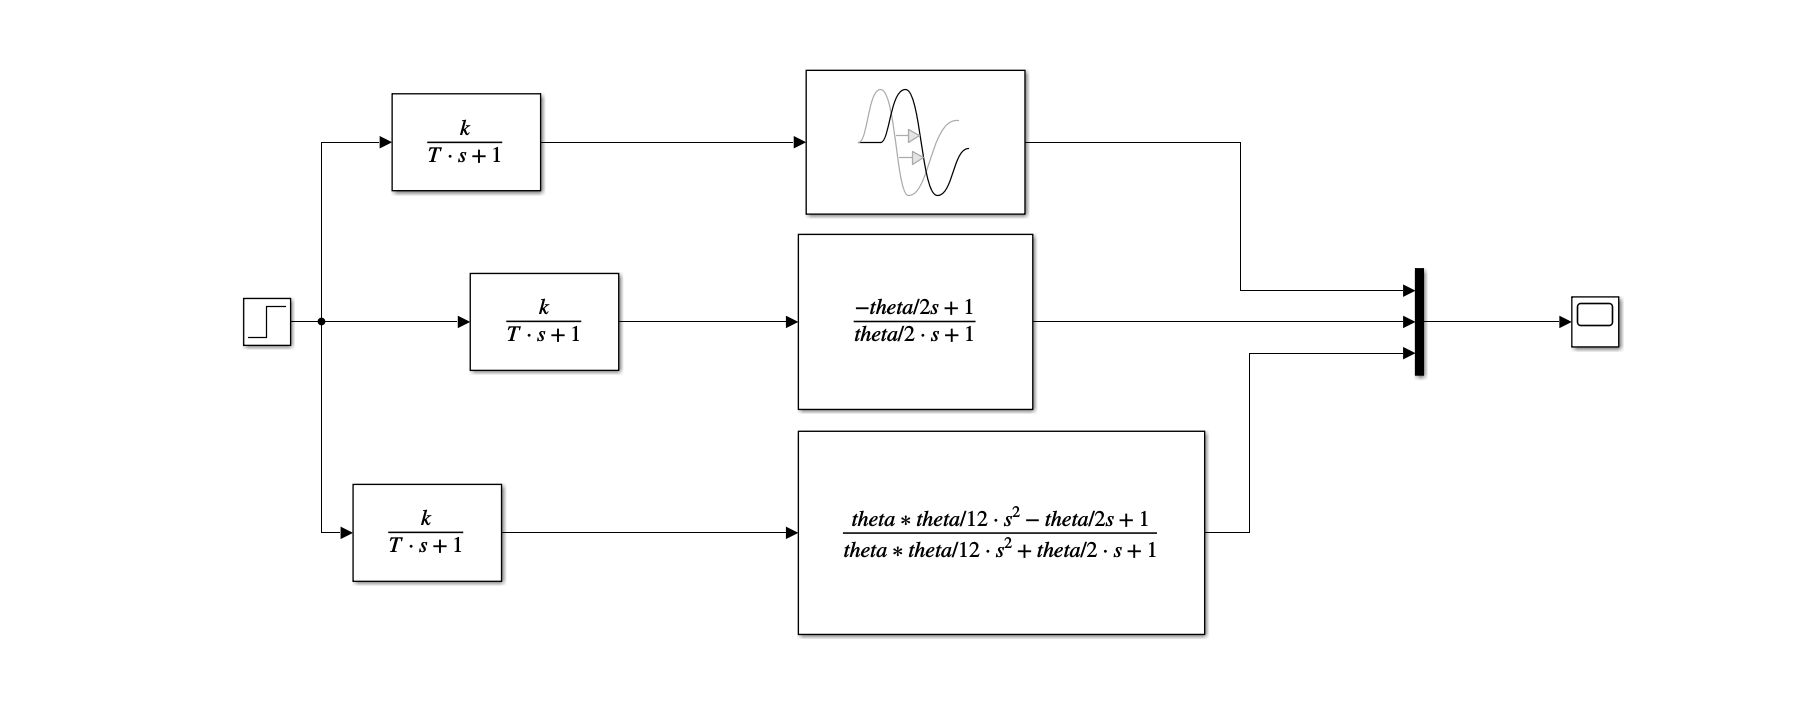

Sygnałem step w pierwszej linii od góry wyzwalałem działanie układu inercyjnego pierwszego rzędu w formie eksponencjalnej gdzie jako członu opóźniającego użyłem  bloczku Transport Delay. Niżej zapisane za pomocą bloczków Transfer Fcn są już pierwszy oraz drugi zapis aproksymacji Pade'go. Całość podpiąłem oczywiście do multipleksera, którego wyjście doprowadziłem do oscyloskopu tak abym mógł zaobserwować wszystkie 3 sygnały jednocześnie. 

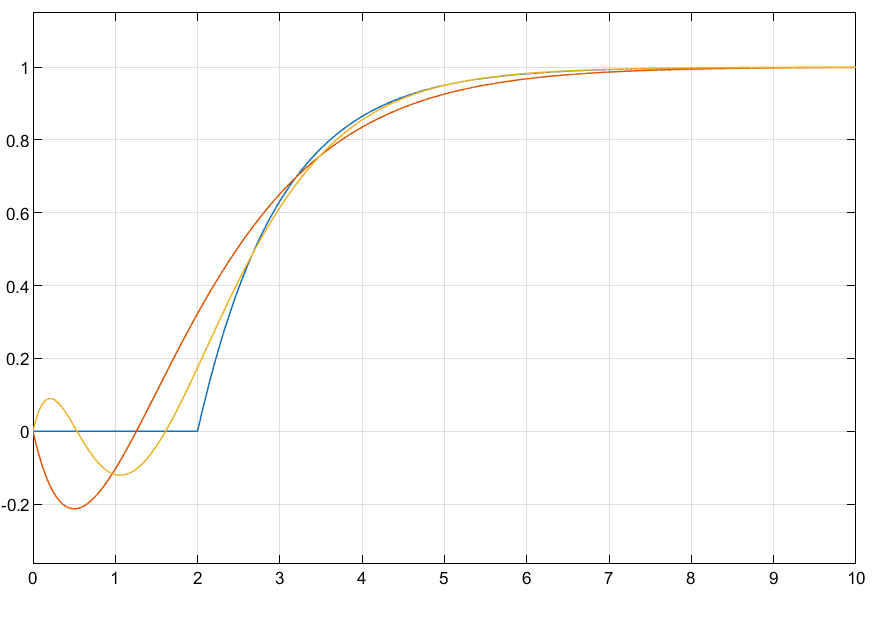

Sygnał niebieski - forma bez aproksymacji Padego , sygnał czerwony - aproksymacja Pade'go pierwszego rzędu, sygnał żółty - aproksymacja Pade'go drugiego rzędu.

Na wykresie widać doskonale to co było spodziewane - im wyższego rzędu przekształceń Pade'go użyję tym wykres staje się bardziej podobny do docelowego. Postać wielomianowa jest prosta w zapisie, przekształceniach oraz analizie. Co ciekawe nie da ona niestety nigdy idealnego rezultatu. Wykres nie będzie nigdy na tyle ostry jaki powinien, ale nie jest to istotne, ponieważ można się na tyle zbliżyć do ideału, że różnica będzie pomijalna.

**Zadanie 2**

Kolejne zadanie polegało na przybliżeniu układu wysokiego rzędu układem niskiego rzędu z opóźnieniem, ponieważ wysoka rzędowość wiąże się z dużą komplikacją obliczeniową. Użyłem zatem do aproksymacji układu 10 rzędu układu inercyjnego II rzędu z opóźnieniem. Współczynniki mianownika a oraz b, a także opóźnienie theta na ten moment miałem dobrać w sposób eksperymentalny.  

global n
k = 1;
T = 1;
theta = 1;
n = 5

n = 5

[licz,mian] = pade(theta,n)

licz = 1.0e+04 *

   -0.0001    0.0030   -0.0420    0.3360   -1.5120    3.0240


mian = 1.0e+04 *

    0.0001    0.0030    0.0420    0.3360    1.5120    3.0240


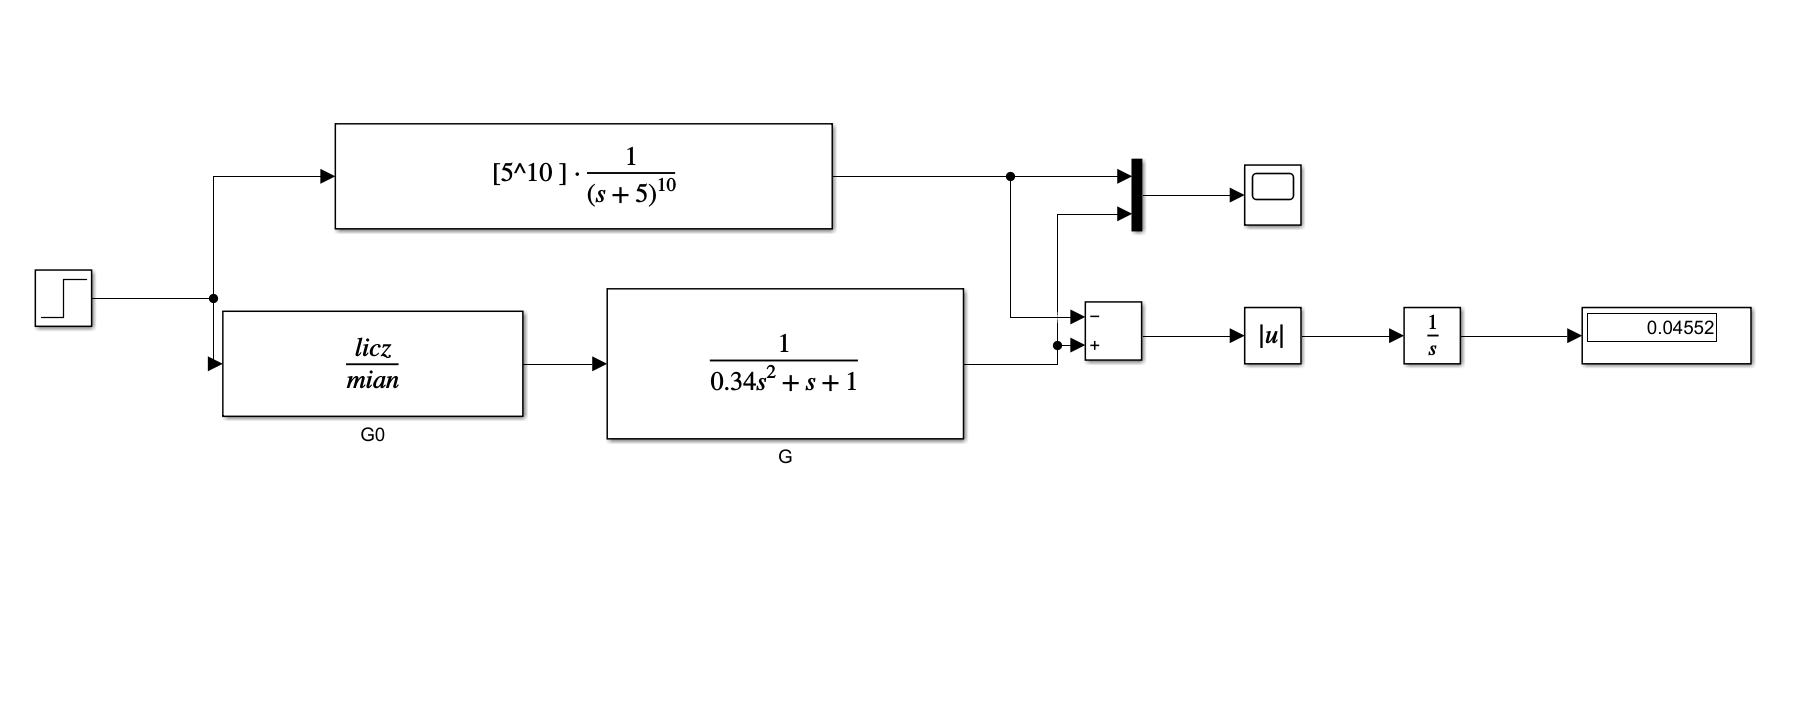

Początkowo zgodnie z podanym w skrypcie wykresem określiłem mniej więcej wartości wzmocnienia k, stałej czasowej T oraz opóźnienia theta. Rzędowość aproksymacji miałem ustawić na wartość 5. Współczynniki członu opóźniającego transmitancji dobrałem funkcją wbudowaną w Matlaba "pade" i prezentują się jak wyżej. W bloczki Simulinka wpisałem już jednak wartości liczbowe, a samych zmiennych literowych użyłem bezpośrednio w poprzednim zadaniu. Sam schemat simulinkowy prezentuje się jak powyżej. Wyższa linia to obiekt o transmitancji 10 rzędu natomiast poniżej jego aproksymacja. obydwa sygnały zostały wyświetlone oscyloskopem oraz podpięte do sumatora dzięki czemu mogłem uzyskać wartość bezwzględną błędu. Jak widać na wyświetlaczu jest on stosukowo niewielki jak na metodę prób i błędów.

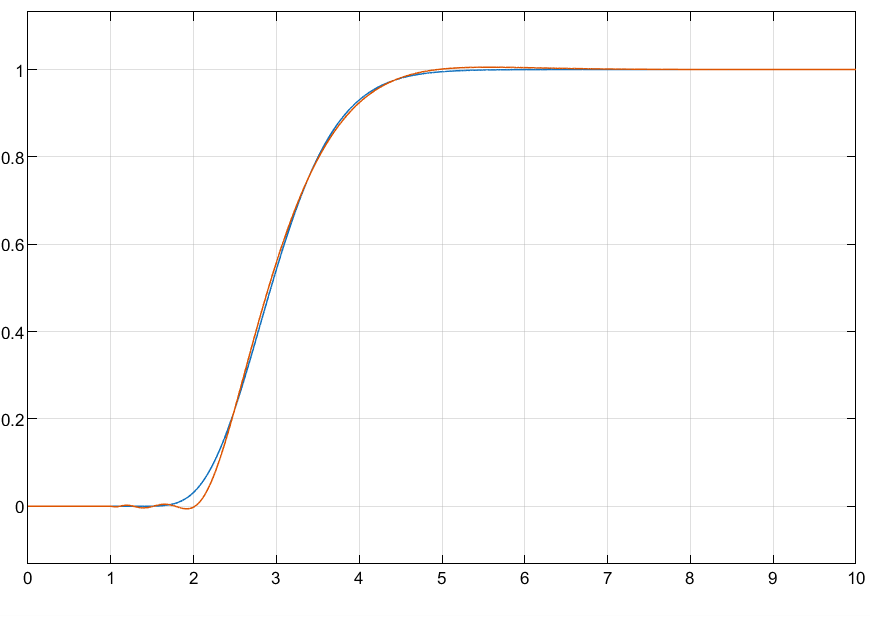

Po dobraniu współczynników ręcznie a = 0.34 b = 1 oraz theta = 1 mogę stwierdzić, że całkiem dokładnie przybliżyłem układ 10 rzędu z niewielkim błędem. Sygnał niebieski to oryginalny natomiast czerwony to jego przybliżanie. 

**Zadanie 3**

Zadanie 3 polegało na wykonaniu zadania 2 używając funkcji optymalizującej. Tutaj posłużyłem się przykładem z poprzednich zajęć gdzie zaszumiony sygnał przybliżałem układem inercyjnym 2 rzędu z opóźnieniem. Tym razem jednak układ 10 rzędu przedstawiłem za pomocą funkcji zpk, natomiast aproksymację jako mnożenie członu Pade'go przez transmitancję obiektu inercyjnego II rzędu. Funkcją fminsearch program znalazł mi współczynniki a,b, theta tak aby błąd był możliwie najmniejszy. Jako początkowe wartości wrzuciłem wszystkie wpółczynniki równe 1 , aby zaobserwować efekt obliczeń numerycznych.

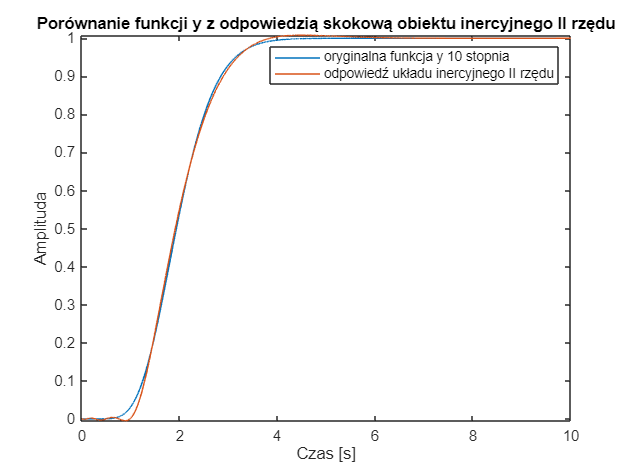

param =     0.3787    1.0301    0.9669


blad = 6.5516e-05

a = 1;
b = 1;
theta = 1;
[param, blad] = fminsearch('ident',[a,b,theta])

[licz_new,mian_new] = pade(0.9669,5);

Powyżej widać, że program przekształcił współczynniki tak aby błąd był możliwie najmniejszy uzyskany współczynnik theta włożyłem ponownie do funkcji pade uzyskując nowy licznik i mianownik członu opóźniającego, natomiast a i b zostały poprawione w bloczkach w simulinku. Parametry uzyskane przez program nieznacznie różnią się od ustalonych przeze mnie ręcznie.

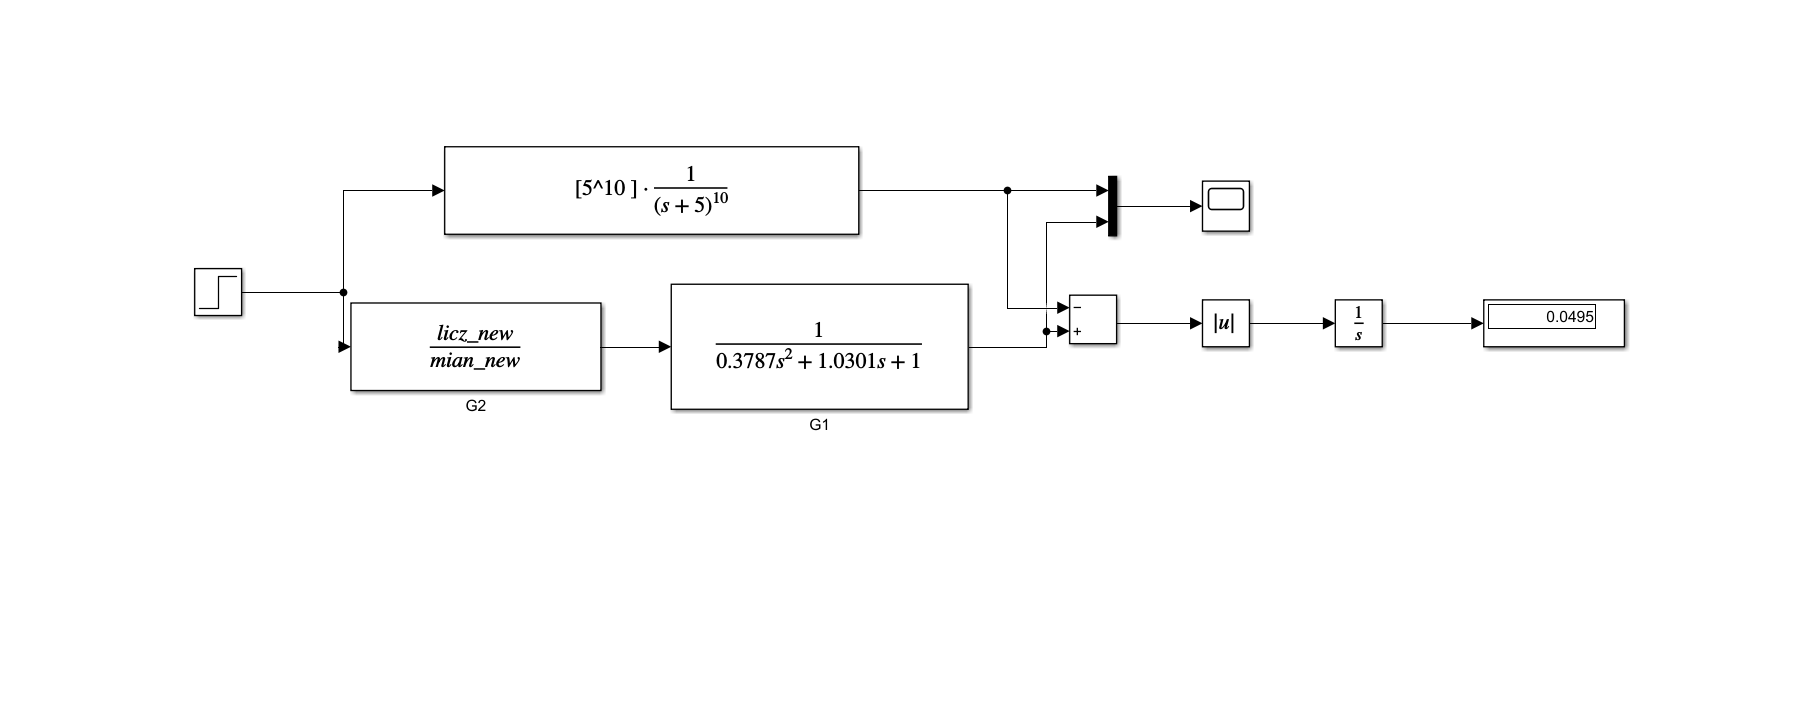

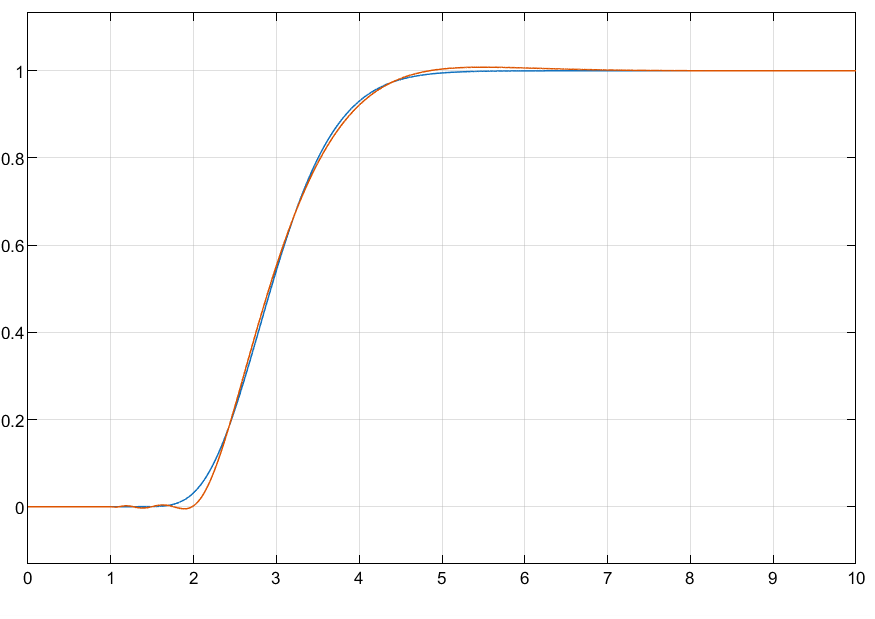

Model simulinkowy oraz wykresy są praktycznie identyczne jak w 2 zadaniu, zmianie uległy tylko współczynniki, które zostały uzyskane przez program funkcją fminsearch. 

Poniżej prezentuję funkcję użytą w celu rozwiązania zadania nr 3.

function blad = ident(X0) 
global n 
t = 0:0.001:10;  
a = X0(1); 
b = X0(2); 
theta = X0(3); 
y = zpk([],ones(1,10) * (-5),5^10);
[licz,mian] = pade(theta,n);

A = tf(licz,mian) * tf([0,1], [a,b,1]); 
%---------------------------------------- ------% 
% tutaj kod, który będzie obliczał % 
% odpowiedź skokową obiektu symulowanego % 
% o takiej samej długości jak odpowiedź % 
% obiektu rzeczywistego % 
%---------------------------------------- ------% 
y1 = step(y,t);
y2 = step(A,t);


plot(t,y1,t,y2), drawnow 
title("Porównanie funkcji y z odpowiedzią skokową obiektu inercyjnego II rzędu") 
xlabel("Czas [s]") 
ylabel("Amplituda") 
legend("oryginalna funkcja y 10 stopnia", "odpowiedź układu inercyjnego II rzędu") 
e = y1 - y2;  
blad = sum(e.^2) / length(e); 
end

**Wnioski**

Aproksymacja Pade'go pozwala uprościć analizę układów z opóźnieniem, gdzie wyższy rząd aproksymacji zapewnia lepsze dopasowanie do rzeczywistego przebiegu. Redukcja rzędowości upraszcza obliczenia, a ręczny dobór parametrów może dać dobre wyniki, choć wymaga doświadczenia. Zastosowanie optymalizacji numerycznej, jak fminsearch, automatyzuje proces, minimalizuje błąd i zapewnia większą precyzję przy mniejszym nakładzie pracy. Mimo że uproszczone modele wprowadzają niewielkie błędy, w praktyce są wystarczające, aby efektywnie analizować i modelować złożone systemy.